# Parameter Effects - Unphysiological Regime a.k.a Parameter Sensitivity Analysis

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Can we use concordance to make better predictions about detecting Time Cells?

DETAILS: 333 uniquely tagged synthetic datasets were analysed on the basis of a variety of numerical procedures (8 algorithms). Subsequently, these scores were used with either Bootstrapping or Otsu's Threshold based methods to classify cells.

Using the configuration for each of the 333 synthetic datasets we split the data based on "Hit Trial Ratio", "Event Width", "Imprecision", and "Noise", and compare the predictions of each of the 8 algorithms against ground truth.

close all
clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1; %Only to select the batch for datasets

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0; %Current
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end

% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!



% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;

%Labels
algoLabels = {'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'};
metricLabels = {'Recall', 'Precision', 'F1 Score'};
methodLabels = {'R2B', 'TI', 'Peak AUC/Std', 'PCA', 'SVM', 'Param. Eqs.'};
methodLabels2 = {'A', 'B', 'C', 'D', 'E', 'F'};
legends1 = {'TPR', 'FPR', 'TNR', 'FNR'};

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma

## Unphysiological Regime - Datasets 1 to 297 (PSA)

For this, consult setupSyntheticDataParams4.m (or configSynth.m)

There are N=3 randomizations per tag.

nShuffles = 3;

% Time Cell Percentage - Basic Order
iTCPb = nShuffles * (1:10);

% Time Cell Percentage - Random Order
iTCPr = nShuffles * (11:20);

% Hit Trial Ratio - Fixed Assignment, Fixed Order
iHTRfixedAfixedO = nShuffles * (21:30);

% Hit Trial Ratio - Fixed Assignment, Random Order
iHTRfixedArndO = nShuffles * (41:50);

% Hit Trial Ratio - Random Assignment, Fixed Order
iHTRrndAfixedO = nShuffles * (11:20);

% Hit Trial Ratio - Random Assignment, Random Order
iHTRrndArndO = nShuffles * (31:40);

% Event Widths - Fixed
iEWfixed = nShuffles * (61:67);

% Event Widths - 1 std. dev. variability
iEWvar = nShuffles * (68:74);

% Uniform Imprecision
iUImp = nShuffles * (75:84);

% Normal Imprecision
iNImp = nShuffles * (85:94);

% Noise
iNoise = nShuffles * (95:99);

## Time Cell Percentage - Basic Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


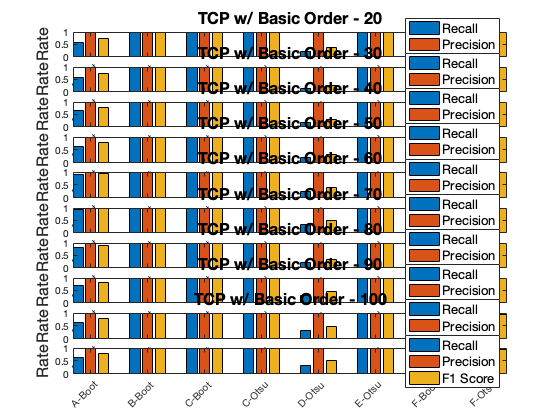

mainBarplotTitle = 'TCP w/ Basic Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iTCPb, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Time Cell Percentage - Basic Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


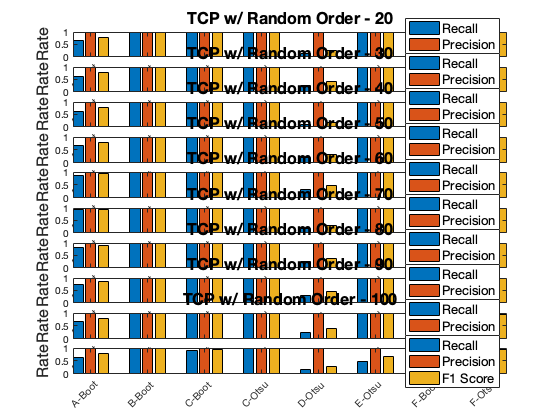

mainBarplotTitle = 'TCP w/ Random Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iTCPr, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Hit Trial Ratio - Fixed Assignment, Fixed Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


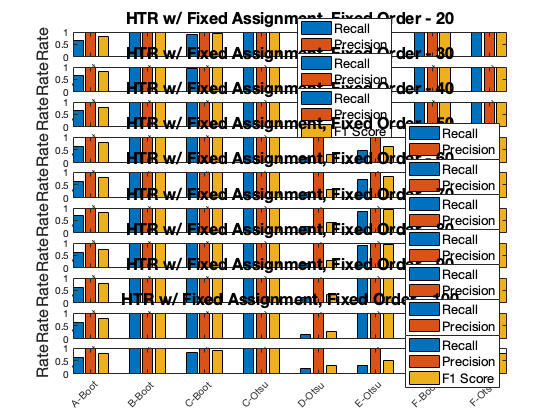

mainBarplotTitle = 'HTR w/ Fixed Assignment, Fixed Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iHTRfixedAfixedO, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Hit Trial Ratio - Fixed Assignment, Random Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


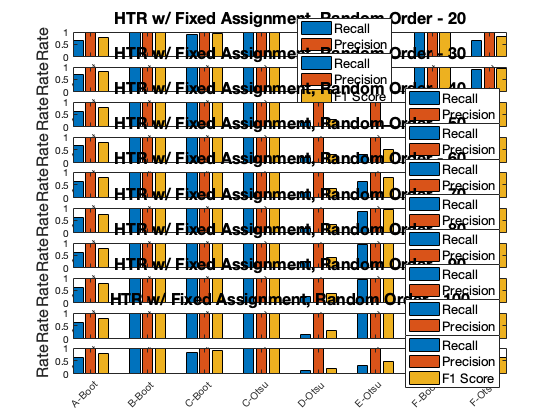

mainBarplotTitle = 'HTR w/ Fixed Assignment, Random Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iHTRfixedArndO, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Hit Trial Ratio - Random Assignment, Fixed Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


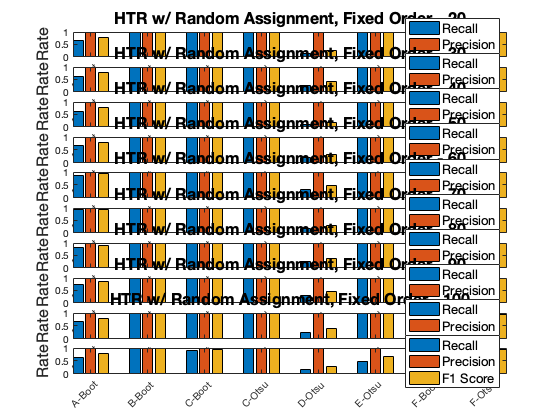

mainBarplotTitle = 'HTR w/ Random Assignment, Fixed Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iHTRrndAfixedO, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Hit Trial Ratio - Random Assignment, Random Order

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


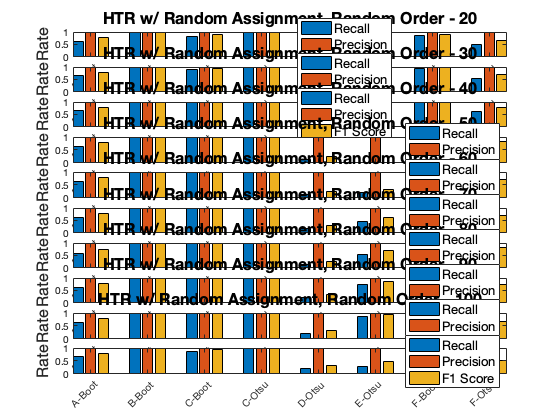

mainBarplotTitle = 'HTR w/ Random Assignment, Random Order - ';

valueList = (10:10:100);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iHTRrndArndO, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Event Widths - Fixed

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


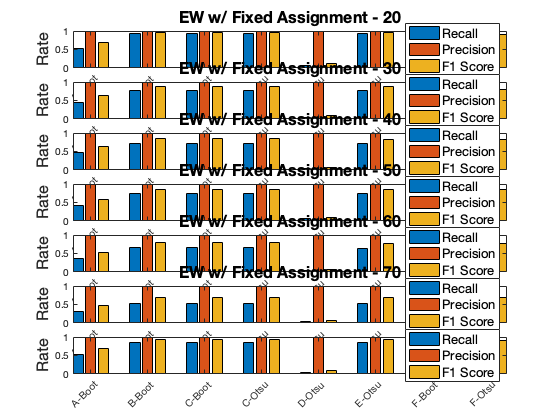

mainBarplotTitle = 'EW w/ Fixed Assignment - ';

valueList = (10:10:70);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iEWfixed, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Event Widths - 1 std. dev. variability

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


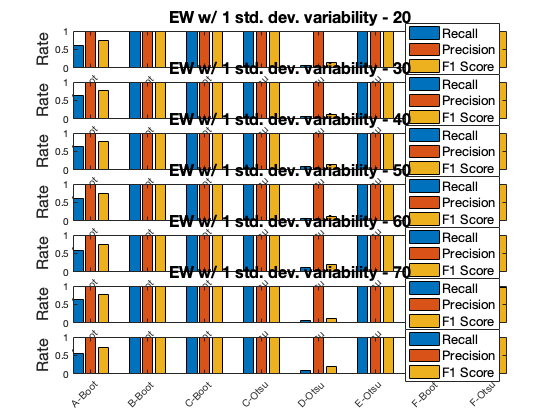

mainBarplotTitle = 'EW w/ 1 std. dev. variability - ';

valueList = (10:10:70);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iEWvar, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Uniform Imprecision

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


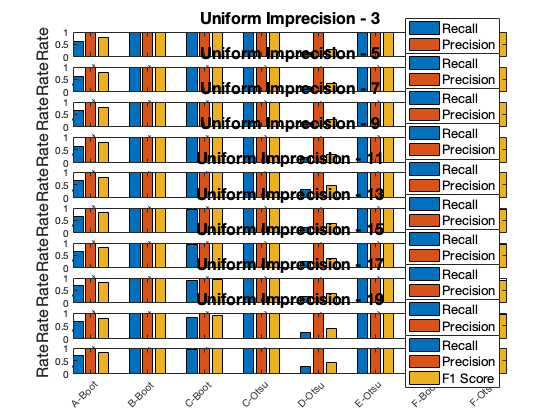

mainBarplotTitle = 'Uniform Imprecision - ';

valueList = (1:2:20);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iUImp, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Normal Imprecision

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


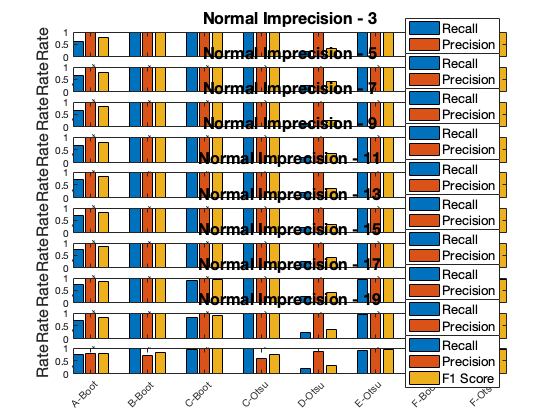

mainBarplotTitle = 'Normal Imprecision - ';

valueList = (1:2:20);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iNImp, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)

## Noise

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


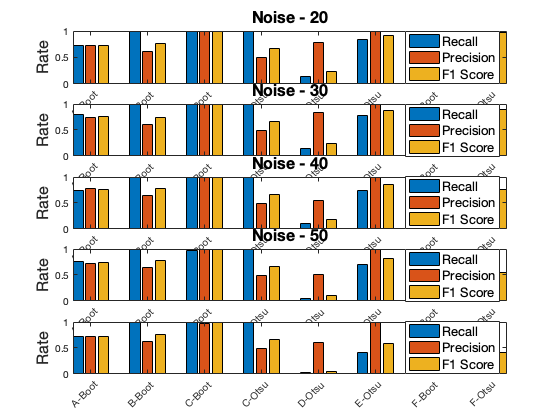

mainBarplotTitle = 'Noise - ';

valueList = (10:10:50);
nExpts = length(valueList);

nShuffles = 3;

plotPSA(nExpts, nShuffles, iNoise, mainBarplotTitle, figureDetails, sdo_batch, cData, ...
    input, valueList, algoLabels, metricLabels)